# Python and MATLAB RRN LSTM Model for Prediction and Forecasting Temperature

This work explores the implementation of Recurrent Neural Network (RNN) and Long Short-Term Memory (LSTM) models using Python and MATLAB for temperature prediction and forecasting. It covers the entire process from setting up the necessary software, importing and preprocessing data, to constructing and training the models. Key techniques include time series analysis, statistical assessment of data distributions, and performance evaluation using metrics like Mean Absolute Error (MAE) and Root Mean Squared Error (RMSE). The guide also demonstrates how to visualize predictions and forecasts, offering a practical and comprehensive approach to leveraging advanced machine learning methods for accurate temperature forecasting.

## **1. Python**

Python is a computer programming language often used to build websites and software, automate tasks, and conduct data analysis.

#### **Setup Python on Computer**

Python needs to be installed to the computer via the following link. ([select the python version that you should install based on your MATLAB version](https://www.mathworks.com/support/requirements/python-compatibility.html).) More information: [https://uk.mathworks.com/support/requirements/python-compatibility.html](https://uk.mathworks.com/support/requirements/python-compatibility.html)

[https://www.python.org/downloads/](https://www.python.org/downloads/)

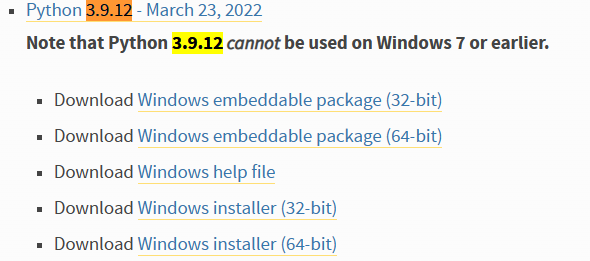

Then Setup exe should be run but the add Python to PATH section must be ticked like below to let windows cmd window or mac/linux terminal to have connect,on to MATLAB. Otherwise python folder's path must be manually added to system variables --> Path section on the computer.

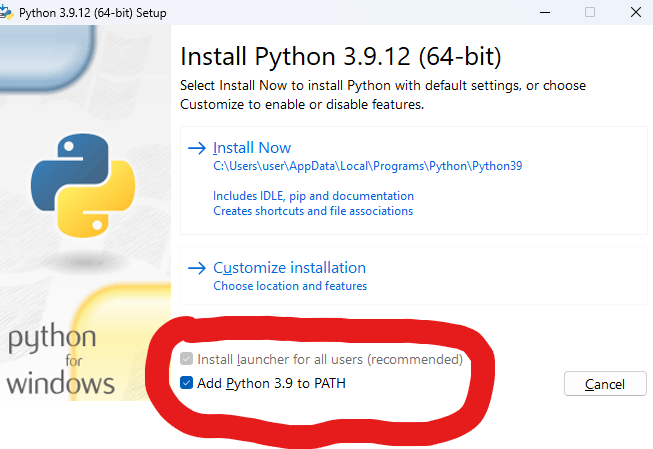

#### **Downloading The Frameworks on Computer**

Open your computer's terminal or command prompt and download the frameworks you need with pip install command. 

For example if you need to download pandas, write the following.

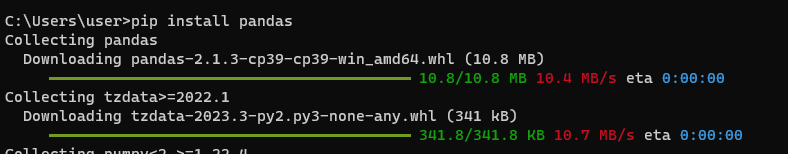

Tensorflow should also be downloaded.

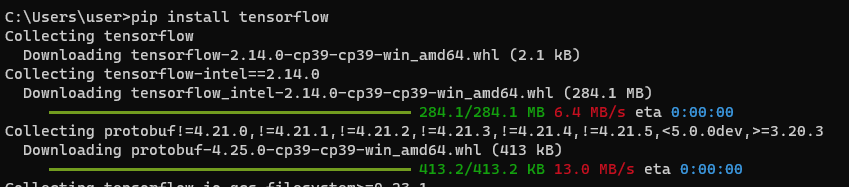

For this application we need to download the frameworks below. 

- pip install requests

- pip install numpy

- pip install matplotlib

- pip install pandas

- pip install seaborn

- pip install scipy

- pip install scikit-learn

- pip install statsmodels

- pip install datetime

- pip install keras

- pip install `"tensorflow<2.11"`

- pip install tk

**It should be noted that MATLAB should be restarted after all these processes.**

#### **Setup Python on MATLAB**

This command will launch Python using 'OutofProcess' to avoid any possible library conflicts.

%Check Python Setup
pyenv

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\Claudia Yasar\AppData\Local\Programs\Python\Python39\python.EXE"
          Library: "C:\Users\Claudia Yasar\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\Claudia Yasar\AppData\Local\Programs\Python\Python39"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "18644"
      ProcessName: "MATLAB"


It should be noted that with the MATLAB 2021b release pyrun command is available. If you write a python code in this command MATLAB will directly run python codes. The documentation is below.

[Pyrun Documnetation](https://www.mathworks.com/help/matlab/ref/pyrun.html)

#### **Import Phase**

Since we all know MATLAB and it is impossible to use Control System Toolbox functions without downloading Control System Toolbox, we need to download some frameworks and libraries that are specialized in machine learning, statistics, and data manipulation in order to obtain our dataset and manipulate it, as we call "pre-processing," to make it ready for the machine learning models that we are using. This is the part where we include the necessary libraries and frameworks such as TensorFlow, Keras, and Pandas.

- TensorFlowThe TensorFlow platform helps you implement best practices for data automation, model tracking, performance monitoring, and model retraining. The most useful advantage of TensorFlow is that it lets you use the GPU instead of the CPU, and GPUs are a lot faster than CPUs when it comes to dealing with machines. If we did not have TensorFlow, it would take plenty more time to deal with the training times of machine learning models.

- KerasKeras is a high-level, deep learning API developed by Google for implementing neural networks. It is written in Python and is used to make the implementation of neural networks easy.

- PandasPandas is an open source Python package that is most widely used for data science, data analysis, and machine learning tasks. It is built on top of another package named Numpy, which provides support for multi-dimensional arrays.

**To import python frameworks on MATLAB first they need to be downloaded on computer(as described in **Downloading The Frameworks on Computer**)**

bdclose
clear all
clc
pyrun("from sklearn.preprocessing import PowerTransformer")
py.importlib.import_module('numpy');

ans =   Python module with properties:

                      polyval: [1×1 py.numpy._ArrayFunctionDispatcher]
                       bytes_: [1×1 py.type]
                       uint64: [1×1 py.type]
                       round_: [1×1 py.numpy._ArrayFunctionDispatcher]
                      polyfit: [1×1 py.numpy._ArrayFunctionDispatcher]
                       seterr: [1×1 py.function]
                       single: [1×1 py.type]
                         rint: [1×1 py.numpy.ufunc]
                       invert: [1×1 py.numpy.ufunc]
                          add: [1×1 py.numpy.ufunc]
                  FPE_INVALID: [1×1 py.int]
                     flatiter: [1×1 py.type]
                       nanmax: [1×1 py.numpy._ArrayFunctionDispatcher]
                          who: [1×1 py.function]
                    vectorize: [1×1 py.type]
                      extract: [1×1 py.numpy._ArrayFunctionDispatcher]
                

% py.importlib.import_module('tensorflow')
% py.importlib.import_module('sklearn')
pyrun("import requests as requests");
pyrun("import numpy as np");
py.importlib.import_module('matplotlib');

ans =   Python module with properties:

                      namedtuple: [1×1 py.function]
                       functools: [1×1 py.module]
                backend_managers: [1×1 py.module]
                    set_loglevel: [1×1 py.function]
                         inspect: [1×1 py.module]
                          figure: [1×1 py.module]
                         patches: [1×1 py.module]
                matplotlib_fname: [1×1 py.function]
                       importlib: [1×1 py.module]
                          artist: [1×1 py.module]
                        gridspec: [1×1 py.module]
                            axes: [1×1 py.module]
                           units: [1×1 py.module]
                       offsetbox: [1×1 py.module]
             rc_params_from_file: [1×1 py.function]
                        tempfile: [1×1 py.module]
                              os: [1×1

pyrun("import matplotlib.pyplot as plt")
pyrun('import pandas as pd')
pyrun("pd.set_option('display.float_format', lambda x: '%.4f' % x)")
pyrun("import seaborn as sns")
pyrun('sns.set_context("paper", font_scale=1.3)')
pyrun("sns.set_style('white')")
pyrun("import matplotlib.ticker as tkr")
pyrun("import tensorflow as tf")
pyrun("from scipy import stats")
pyrun("from statsmodels.tsa.stattools import adfuller")
pyrun("from sklearn import preprocessing")
pyrun("from sklearn import preprocessing")
pyrun("from statsmodels.tsa.stattools import pacf")
pyrun("from datetime import datetime,timedelta")
pyrun("import math")
pyrun("import math as mth")
pyrun("import keras as keras")
pyrun("TF_ENABLE_ONEDNN_OPTS=0")
pyrun("TF_DISABLE_MKL=1")
pyrun(["from keras.models import Sequential",...
    "from keras.layers import Dense",...
    "from keras.layers import LSTM", ...
    "from keras.layers import Dropout",...
    "from keras.layers import *",...
    "from sklearn.preprocessing import MinMaxScaler",...
    "from sklearn.metrics import mean_squared_error",...
    "from sklearn.metrics import mean_absolute_error",...
    "from keras.callbacks import EarlyStopping",...
    "from scipy.stats import boxcox, shapiro",...
    "sns.set()"])
pyrun("import tkinter")
pyrun("print(tf.__version__)")

2.10.1


## **2. Data Importing - Preprocessing**

#### **Importing the Dataset**

The date needs to be exported in the code. The Pandas library helps us read the dataset we have.

df = pyrun("df = pd.read_csv('seattle-weather.csv')","df");
pyrun("print(df)")

            date  precipitation  temp_max  temp_min   wind  weather
0     2012-01-01         0.0000   12.8000    5.0000 4.7000  drizzle
1     2012-01-02        10.9000   10.6000    2.8000 4.5000     rain
2     2012-01-03         0.8000   11.7000    7.2000 2.3000     rain
3     2012-01-04        20.3000   12.2000    5.6000 4.7000     rain
4     2012-01-05         1.3000    8.9000    2.8000 6.1000     rain
...          ...            ...       ...       ...    ...      ...
1456  2015-12-27         8.6000    4.4000    1.7000 2.9000     rain
1457  2015-12-28         1.5000    5.0000    1.7000 1.3000     rain
1458  2015-12-29         0.0000    7.2000    0.6000 2.6000      fog
1459  2015-12-30         0.0000    5.6000   -1.0000 3.4000      sun
1460  2015-12-31         0.0000    5.6000   -2.1000 3.5000      sun

[1461 rows x 6 columns]


The dataset has to be manipulated with respect to our needs for the machine learning model.

In the dataset, we have the maximum and minimum temperature values for the represented day. But I want to forecast the average temperature. So I just added a new column to my dataset.

df_max = pyrun("df_max = df['temp_max']","df_max");
df_min =  pyrun("df_min = df['temp_min']","df_min");
pyrun("df['temp_average'] = (df_max + df_min)/2")
df;

df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.int]
     values: [1×1 py.numpy.ndarray]

                date  precipitation  temp_max  ...   wind  weather temp_average
    0     2012-01-01         0.0000   12.8000  ... 4.7000  drizzle       8.9000
    1     2012-01-02        10.9000   10.6000  ..

#### **Creating a New Dataframe for Prediction**

I want to compare my forecast results with my forecasts.

I need to create a new dataframe that does not include the forecasted values I want; otherwise, my machine learning model would know about the values that I want to forecast, and it wouldn't be a forecast after all.

new_df = pyrun("new_df = df.iloc[1:-58]","new_df");
new_df

new_df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.int]
     values: [1×1 py.numpy.ndarray]

                date  precipitation  temp_max  ...   wind  weather temp_average
    1     2012-01-02        10.9000   10.6000  ... 4.5000     rain       6.7000
    2     2012-01-03         0.8000   11.7000

#### **Date Objects**

We want to create date objects to display our plots' x axis. Otherwise we would have indices.

d1 = pyrun("d1 = datetime(2012,1,1,1,0,0,0)","d1");
numdays = pyrun("numdays = len(new_df)","numdays");
numdays_forecast = pyrun("numdays_forecast = len(df)","numdays_forecast");
% dateList = pyrun("dateList = []","dateList");
% dateList_forecast = pyrun("dateList_forecast = []","dateList_forecast");
% for x = 0:single(numdays)
% pyrun("dateList.append(d1 + timedelta(days = x))",x = x)
% end
% pyrun("print(dateList)")
% for x = 0:single(numdays_forecast)
% pyrun("dateList_forecast.append(d1 + timedelta(days = x))",x = x)
% end
% pyrun("print(dateList_forecast)")
% dateList = datetime(2012,1:single(numdays),1,1,0,0)
% dateList.Format = 'yyyy MMM dd'
% for x = 1:(single(numdays)-1)
% dateList(1,x+1) = dateList(1,x) + days(1)
% end
startdate = datetime(2012,1,1);
dateList = startdate + days(1:(single(numdays)));
dateList.Format = 'yyyy MMM dd';
dateList_forecast = startdate + days(1:(single(numdays_forecast)));
dateList_forecast.Format = 'yyyy MMM dd';

#### **Checking the Dataframe**

We need tp be sure that our dataset does not have any missing cells. For that we are using .dropna command. If we have missing cells we have to fill them using some methods.

pyrun(["print('Number of rows and columns before removing missing values:', new_df.shape)",...
    "print('The time series starts from before removing missing values: ', new_df.date.min())",...
    "print('The time series ends on before removing missing values: ', new_df.date.max())"])

Number of rows and columns before removing missing values: (1402, 7)
The time series starts from before removing missing values:  2012-01-02
The time series ends on before removing missing values:  2015-11-03


new_df = pyrun("new_df = new_df.dropna(subset=['temp_average'])","new_df");
pyrun(["print('Number of rows and columns after removing missing values:', new_df.shape)",...
    "print('The time series starts from before removing missing values: ', new_df.date.min())",...
    "print('The time series ends on before removing missing values: ', new_df.date.max())"])

Number of rows and columns after removing missing values: (1402, 7)
The time series starts from before removing missing values:  2012-01-02
The time series ends on before removing missing values:  2015-11-03


## **3. Gaussian Distribution**

A distribution is simply a collection of the value and frequency of a given observation, like the age of a population. Samples of an ideal Gaussian distribution (aka normal distribution or bell curve) follow the bell curve, meaning values are more likely to be around the mean than at the extremes.

#### **Why is the Gaussian distribution Important in Machine Learning**

In machine learning, cost functions or neuron potential values are the quantities that are expected to be the sum of many independent processes (such as input features or activation potential of the last layer) and often have distributions that are nearly normal. Knowing the gaussian nature of the dataset, one can continue to use parametric statistics.

Some ML models need to be converted into Gaussian distributions with some methods, such as power transforms, differential transforms, and so on.

But the model we will be using today is looking for hidden patterns and does not need the dataset to have a gaussian distribution.

normaltest = pyrun("stat = stats.normaltest(new_df.temp_average)","stat");

normaltest =   Python NormaltestResult with properties:

    pvalue
    statistic

    NormaltestResult(statistic=71.87407938613488, pvalue=2.470256014434559e-16)


stat = normaltest.statistic

stat = 71.8741

p = normaltest.pvalue

p = 2.4703e-16

disp(["Statistic = %", num2str(stat),' P = %', num2str(p)])

    "Statistic = %"    "71.8741"    " P = %"    "2.4703e-16"



alpha = 0.05;
if (p > alpha)
    pyrun("print('Data looks Gaussian (fail to reject H0)')")
else
    pyrun("print('Data does not look Gaussian (reject H0)')")
end

Data does not look Gaussian (reject H0)


#### **Skewness**

Skewness is usually described as a measure of a dataset’s symmetry – or lack of symmetry. A perfectly symmetrical data set will have a skewness of 0. The normal distribution has a skewness of 0.

#### **Kurtosis**

Kurtosis describes the "fatness" of the tails found in probability distributions. The normal distribution has a kurtosis of exactly 3.0.

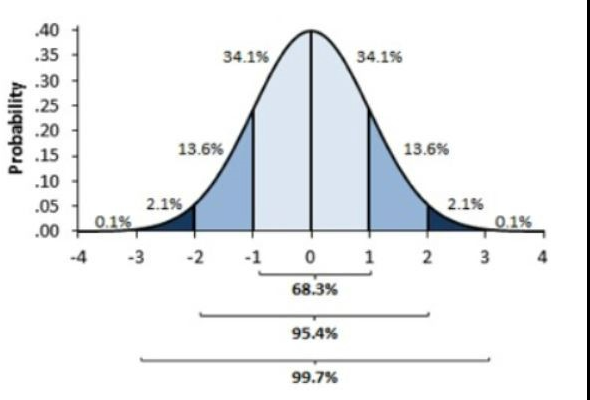

% pyrun("sns.displot([1,2,3,4,5])")
new_df_temp_average = pyrun("new_df_temp_average = new_df.temp_average","new_df_temp_average");

new_df_temp_average =   Python Series with properties:

                          T: [1×1 py.pandas.core.series.Series]
                      array: [1×1 py.pandas.core.arrays.numpy_.NumpyExtensionArray]
                         at: [1×1 py.pandas.core.indexing._AtIndexer]
                      attrs: [1×1 py.dict]
                       axes: [1×1 py.list]
                      dtype: [1×1 py.numpy.dtypes.Float64DType]
                     dtypes: [1×1 py.numpy.dtypes.Float64DType]
                      empty: 0
                      flags: [1×1 py.pandas.core.flags.Flags]
                    hasnans: 0
                        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
                       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
                      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
    is_monotonic_decreasing: 0
    is_monotonic_increasing: 0
                  is_un

new_df_temp_average_values = double(new_df_temp_average.tolist());

histfit(new_df_temp_average_values)
xlabel("Temperature Average")
ylabel("Density")

pyrun(["print( 'Kurtosis of normal distribution: {}'.format(stats.kurtosis(new_df.temp_average)))",...
    "print( 'Skewness of normal distribution: {}'.format(stats.skew(new_df.temp_average)))"])

Kurtosis of normal distribution: -0.7000551623133595
Skewness of normal distribution: 0.0027819866989865125


#### **Probability Plot**

The probability plot is a graphical technique for assessing whether or not a data set follows a given distribution such as the normal or Weibull. The data are plotted against a theoretical distribution in such a way that the points should form approximately a straight line. Departures from this straight line indicate departures from the specified distribution.

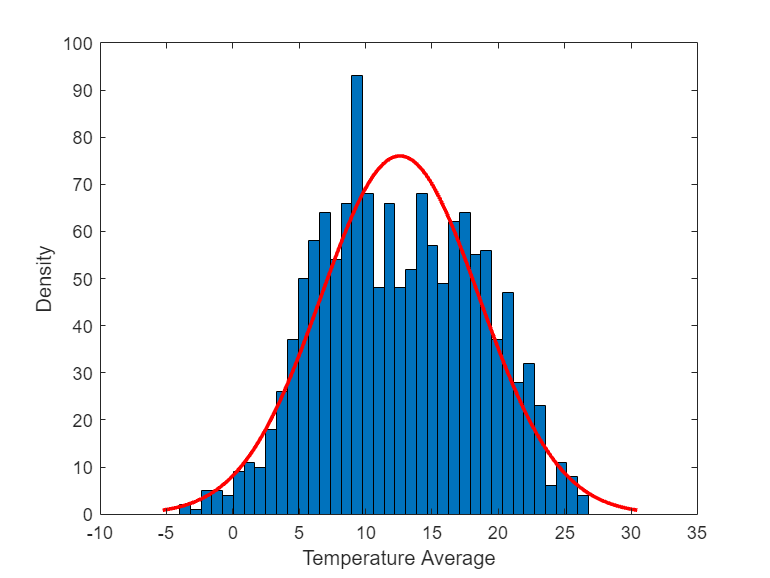

rng('default')
tiledlayout(1,2)

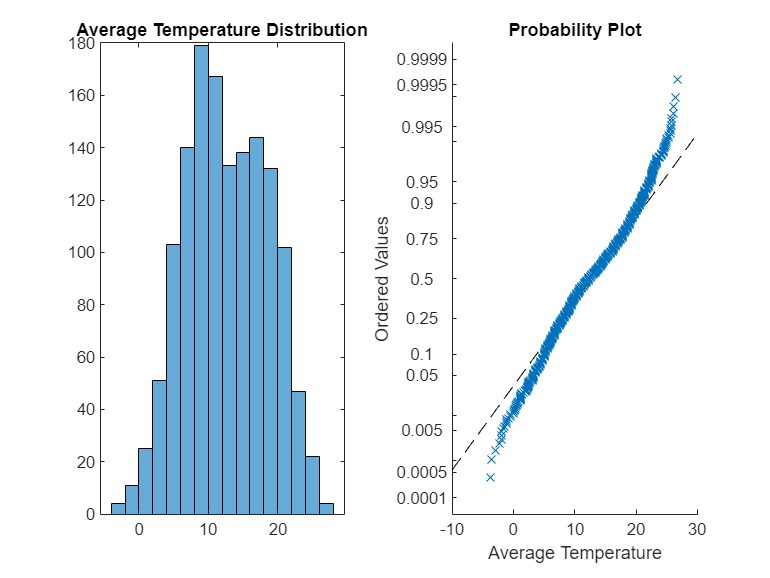

nexttile
histogram(new_df_temp_average_values)
title("Average Temperature Distribution")
nexttile
probplot(new_df_temp_average_values)
title("Probability Plot")
ylabel("Ordered Values")
xlabel("Average Temperature")

pyrun("print(df.describe().T)")

                  count    mean    std     min     25%     50%     75%     max
precipitation 1461.0000  3.0294 6.6802  0.0000  0.0000  0.0000  2.8000 55.9000
temp_max      1461.0000 16.4391 7.3498 -1.6000 10.6000 15.6000 22.2000 35.6000
temp_min      1461.0000  8.2348 5.0230 -7.1000  4.4000  8.3000 12.2000 18.3000
wind          1461.0000  3.2411 1.4378  0.4000  2.2000  3.0000  4.0000  9.5000
temp_average  1461.0000 12.3369 5.9981 -3.8000  7.7500 11.9500 17.2000 26.7000


## **4. Time Series**

Before building the model, it is good to see the values that you need to deal with. We can see our model is seasonal, which means it is periodic over years.

timeseries = figure

timeseries =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


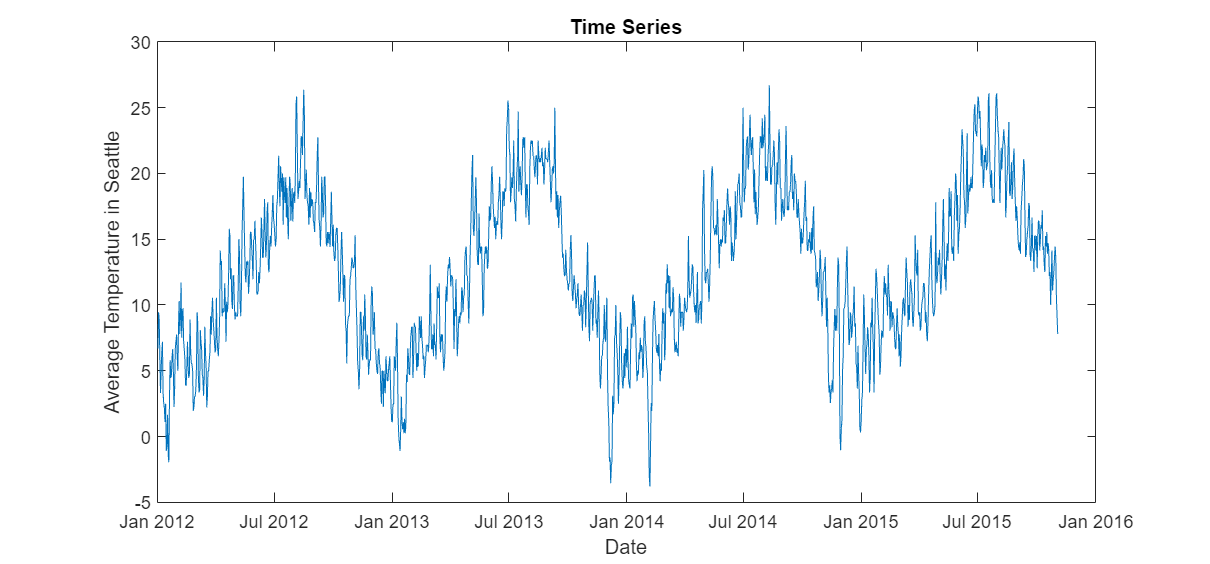

plot(dateList,new_df_temp_average_values)
ylabel('Average Temperature in Seattle')
xlabel("Date")
title('Time Series')
timeseries.Position(3:4) = [880 410];

#### **Rolling Mean**

The rolling average or moving average is the simple mean of the last ‘n’ values. It can help us in finding trends that would be otherwise hard to detect. Also, they can be used to determine long-term trends. You can simply calculate the rolling average by summing up the previous ‘n’ values and dividing them by ‘n’ itself.

#### **Rolling Standard Deviation**

Standard deviation is a number that describes how spread out the values are. A low standard deviation means that most of the numbers are close to the mean (average) value. A high standard deviation means that the values are spread out over a wider range. Rolling standard deviation is used when we expect the standard deviation to change over time.

rol_mean = movmean(new_df_temp_average_values,30)

rol_mean =     4.1867    4.0281    3.7088    3.3944    3.3763    3.4975    3.5429    3.5955    3.7043    3.8271    3.8740    3.8115    3.8056    3.9071    4.0207    4.1450    4.1250    3.9767    3.9567    4.1050    4.2550    4.3850    4.5617    4.5717    4.7750    5.0167    5.1850    5.3700    5.4800    5.6467    5.7950    5.9150    6.2017    6.4433    6.4900    6.4550    6.6033    6.6600    6.6417    6.6050    6.6050    6.5950    6.5483    6.4283    6.2900    6.1517    6.1250    6.2733    6.2850    6.0900


rol_std = movstd(new_df_temp_average_values,30)

rol_std =     3.2147    3.1698    3.3395    3.5036    3.4059    3.3590    3.2806    3.2110    3.1803    3.1680    3.1102    3.0639    3.0046    2.9970    3.0059    3.0311    3.0156    2.8495    2.8156    3.0280    3.0974    3.2096    3.4604    3.4687    3.5719    3.6569    3.6389    3.5644    3.5235    3.3135    3.1205    3.0233    2.6958    2.2234    2.1636    2.1836    2.1938    2.1647    2.1719    2.1810    2.1810    2.2023    2.2803    2.3678    2.4413    2.4730    2.4779    2.5407    2.5511    2.4554


f = figure

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


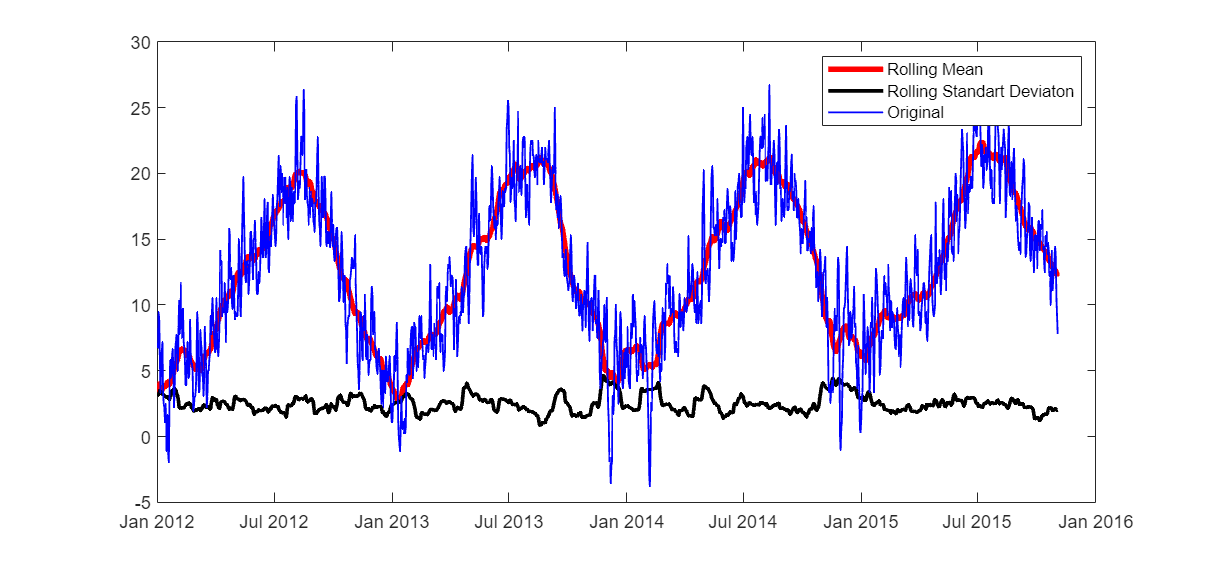

plot(dateList,rol_mean,"LineWidth",3,"Color","r")
hold on
plot(dateList,rol_std,"LineWidth",2,"Color","k")
hold on 
plot(dateList,new_df_temp_average_values,"LineWidth",1,"Color","b")
legend("Rolling Mean", "Rolling Standart Deviaton","Original")
f.Position(3:4) = [880 410];

#### **Correlation**

Correlation is used to find the relationship between two variables which is important in real life because we can predict the value of one variable with the help of other variables, who is being correlated with it. A positive correlation indicates two variables that tend to move in the same direction. A negative correlation indicates two variables that tend to move in opposite directions.

#### **Autocorrelation**

- Autocorrelation represents the degree of similarity between a given time series and a lagged version of itself over successive time intervals.

- Autocorrelation measures the relationship between a variable's current value and its past values.

- An autocorrelation of +1 represents a perfect positive correlation, while an autocorrelation of negative 1 represents a perfect negative correlation. Technical analysts can use autocorrelation to measure how much influence past prices for a security have on its future price. Hence +1 is the perfect autocorrelation for time series predictions.

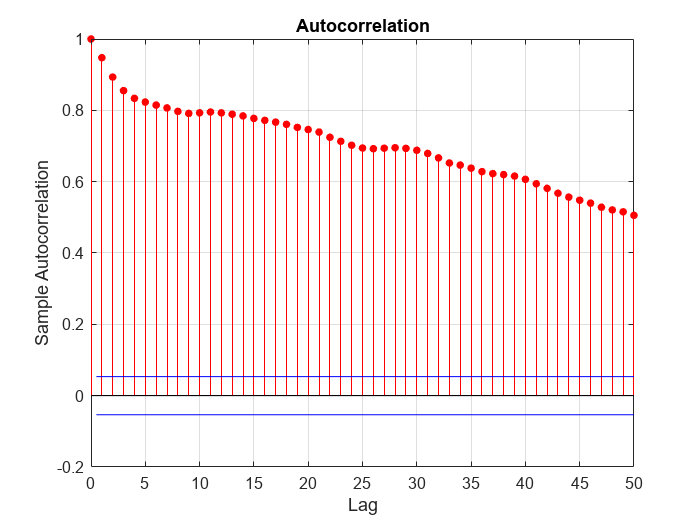

figure
autocorr(new_df_temp_average_values,NumLags=50)
title("Autocorrelation")

## **5. Train and Test Dataset**

We have to train a model in order to make our model make predictions. If we don't train our model well enough for predictions, the result will come out bad.

In ML, a usually trained model is separated from 80% of the actual data. We want our model to find and learn the hidden parameters inside this model, implement what it learned onto the test dataset, and actually predict this test dataset.

#### **Scaling a Model**

The ML algorithm works better when features are relatively similar in scale and close to normal distribution.

Min-Max scaling is a normalization technique that enables us to scale data in a dataset to a specific range (0–1 in our case) using each feature’s minimum and maximum value.

Unlike standard scaling, where data are scaled based on the standard normal distribution (with mean = 0 and standard deviation = 1), the min-max scaler uses each column’s minimum and maximum value to scale the data series.

The scale of data for some features may be significantly different from those of others, which may harm the performance of our models. It is especially the case with algorithms that rely on a measure of distance, such as neural networks and KNN.

dataset = pyrun("dataset = new_df.temp_average.values","dataset");
dataset = pyrun("dataset = dataset.astype('float32')","dataset");
dataset = pyrun("dataset = np.reshape(dataset, (-1, 1))","dataset");
scaler = pyrun("scaler = MinMaxScaler(feature_range=(0, 1))","scaler");
dataset = pyrun("dataset = dataset = scaler.fit_transform(dataset)","dataset");
train_size = pyrun("train_size = int(len(dataset) * 0.80)","train_size");
test_size = pyrun("test_size = len(dataset) - train_size","test_size");
train = pyrun("train = dataset[0:train_size,:]","train");
test = pyrun("test = dataset[train_size:len(dataset),:]","test");
disp(["test data size: ",num2str(single(test_size))])

    "test data size: "    "281"



disp(["train data size: ",num2str(single(train_size))])

    "train data size: "    "1121"



train;

train =   Python ndarray:

    0.3443
    0.4344
    0.4164
    0.3164
    0.2328
    0.2885
    0.3344
    0.3607
    0.2344
    0.2066
    0.1967
    0.1607
    0.2066
    0.0885
    0.1066
    0.1787
    0.0787
    0.0607
    0.2246
    0.3148
    0.2705
    0.2787
    0.3246
    0.3426
    0.2885
    0.1984
    0.2443
    0.3426
    0.3607
    0.3787
    0.3246
    0.2885
    0.3967
    0.4623
    0.3803
    0.4164
    0.5082
    0.3705
    0.4344
    0.4443
    0.3623
    0.3426
    0.3148
    0.2525
    0.2525
    0.2967
    0.3607
    0.2984
    0.2705
    0.2803
    0.4164
    0.3344
    0.3066
    0.3066
    0.2885
    0.1885
    0.1984
    0.2246
    0.2246
    0.2426
    0.2984
    0.4344
    0.4082
    0.2705
    0.2344
    0.2426
    0.3902
    0.3607
    0.3426
    0.2803
    0.2705
    0.2262
    0.2705
    0.3984
    0.3344
    0.2984
    0.1967
    0.2246
    0.2885
    0.2885
    0.3164
    0.334

disp("Dataset Length = "+ length(dataset.tolist()))

Dataset Length = 1402


disp("Train Dataset Length = " + (length(train.tolist())))

Train Dataset Length = 1121


disp("Test Dataset Length = " + length(test.tolist()))

Test Dataset Length = 281


#### **Time Steps**

Time steps are a way of examining and analyzing your data through specified time intervals.

By setting the time steps, we define how many steps back our model should look for hidden patterns. We can forecast future steps in time.

We set the time step numbers and create our training and test dataset according to this time step.

look_back = 7;
[X_train, Y_train] = create_dataset(train, look_back);
[X_test, Y_test] = create_dataset(test, look_back);
% X_train = pyrun("X_train = numpy.array(X_train)","X_train");
% X_test = pyrun("X_test = numpy.array(X_test)","X_test");
% Y_train = pyrun("Y_train = numpy.array(Y_train)","Y_train");
% Y_test = pyrun("Y_test = numpy.array(Y_test)","Y_test");
pyrun("print(X_train.shape)",X_train = X_train)

(1114, 7, 1)


pyrun("print(X_test.shape)",X_test = X_test)

(274, 7, 1)


pyrun("print(Y_train.shape)",Y_train = Y_train)

(1114,)


pyrun("print(Y_test.shape)",Y_test = Y_test)

(274,)



pyrun("print(X_train)",X_train = X_train);

[[[0.34426227]
  [0.4344262 ]
  [0.4163934 ]
  ...
  [0.23278686]
  [0.28852457]
  [0.33442622]]

 [[0.4344262 ]
  [0.4163934 ]
  [0.31639344]
  ...
  [0.28852457]
  [0.33442622]
  [0.36065573]]

 [[0.4163934 ]
  [0.31639344]
  [0.23278686]
  ...
  [0.33442622]
  [0.36065573]
  [0.23442622]]

 ...

 [[0.3967213 ]
  [0.4704918 ]
  [0.38852456]
  ...
  [0.23442622]
  [0.3786885 ]
  [0.46065572]]

 [[0.4704918 ]
  [0.38852456]
  [0.34262294]
  ...
  [0.3786885 ]
  [0.46065572]
  [0.5426229 ]]

 [[0.38852456]
  [0.34262294]
  [0.23442622]
  ...
  [0.46065572]
  [0.5426229 ]
  [0.52459013]]]


pyrun("print(X_test)",X_test = X_test);

[[[0.44262293]
  [0.40655738]
  [0.3786885 ]
  ...
  [0.29672128]
  [0.35081965]
  [0.38852456]]

 [[0.40655738]
  [0.3786885 ]
  [0.2786885 ]
  ...
  [0.35081965]
  [0.38852456]
  [0.38032785]]

 [[0.3786885 ]
  [0.2786885 ]
  [0.29672128]
  ...
  [0.38852456]
  [0.38032785]
  [0.3704918 ]]

 ...

 [[0.5885246 ]
  [0.4885246 ]
  [0.5163934 ]
  ...
  [0.5704918 ]
  [0.59836066]
  [0.5721311 ]]

 [[0.4885246 ]
  [0.5163934 ]
  [0.5344262 ]
  ...
  [0.59836066]
  [0.5721311 ]
  [0.4704918 ]]

 [[0.5163934 ]
  [0.5344262 ]
  [0.5704918 ]
  ...
  [0.5721311 ]
  [0.4704918 ]
  [0.42459014]]]


pyrun("print(Y_train)",Y_train = Y_train)

[0.36065573 0.23442622 0.20655736 ... 0.5426229  0.52459013 0.4885246 ]


pyrun("print(Y_test)",Y_test = Y_test);

[0.38032785 0.3704918  0.4786885  0.52459013 0.4786885  0.50655735
 0.4786885  0.4704918  0.42622948 0.552459   0.4901639  0.4704918
 0.38852456 0.46229506 0.46065572 0.3967213  0.4344262  0.42459014
 0.4163934  0.3704918  0.34426227 0.34262294 0.39836064 0.44426227
 0.39836064 0.3786885  0.32459015 0.3786885  0.29836065 0.3262295
 0.38852456 0.42459014 0.46229506 0.4704918  0.43278685 0.42459014
 0.50655735 0.5704918  0.5344262  0.50655735 0.39836064 0.45245898
 0.4147541  0.4983606  0.5163934  0.4983606  0.4786885  0.4163934
 0.39836064 0.4344262  0.4786885  0.62622947 0.5704918  0.5344262
 0.5262295  0.5901639  0.4344262  0.42622948 0.4344262  0.38852456
 0.39836064 0.44426227 0.46229506 0.4704918  0.50655735 0.50655735
 0.48032784 0.4081967  0.4344262  0.38032785 0.36229506 0.40655738
 0.48032784 0.5344262  0.5704918  0.60655737 0.62622947 0.5163934
 0.46229506 0.4344262  0.42459014 0.4344262  0.45245898 0.70819664
 0.5262295  0.50655735 0.5344262  0.5704918  0.552459   0.5901639
 

See [Create Dataset Function](matlab:open('./create_dataset.m')) for function details.

We are reshaping our dataset to define the output numbers that we want.

Since we wanted only one output, we reshaped our model according to that.

Y_train = pyrun("Y_train = np.reshape(Y_train, (int(len(X_train)), 1))","Y_train",X_train = X_train,look_back = look_back);
Y_test = pyrun("Y_test = np.reshape(Y_test, (int(len(X_test)), 1))","Y_test",X_test = X_test,look_back = look_back);% pyrun("print(Y_train.shape)",Y_train = Y_train)
pyrun("print(Y_test.shape)",Y_test = Y_test)

(274, 1)


#### **Hidden Layer (Neuron Numbers)**

Hidden Layers detect the neuron numbers that our models will use. There is a common formula to obtain hidden layers.

Hidden Layers = Input Numbers ÷ (α * (Output Numbers + Time Steps))

Where α is an integer between 2 and 10

X_train = pyrun("X_train.reshape(X_train.shape[0],1,X_train.shape[1])","X_train",X_train = X_train);
X_test = pyrun("X_test.reshape(X_test.shape[0],1,X_test.shape[1])","X_test",X_test = X_test);
pyrun("print(X_train.shape)")

(1114, 7, 1)



realvalues = Y_test;
hidden_layers = pyrun("hidden_layers = int(X_test.shape[0]/(4*(X_test.shape[1]+X_test.shape[2])))","hidden_layers",look_back = look_back,X_test = X_test)

hidden_layers =   Python int with properties:

    denominator: [1×1 py.int]
           imag: [1×1 py.int]
      numerator: [1×1 py.int]
           real: [1×1 py.int]

    8


## **6. Recurrent Neural Networks**

Recurrent Neural Network(RNN) is a type of Neural Network where the output from the previous step are fed as input to the current step. In traditional neural networks, all the inputs and outputs are independent of each other, but in cases like when it is required to predict the next word of a sentence, the previous words are required and hence there is a need to remember the previous words. Thus RNN came into existence, which solved this issue with the help of a Hidden Layer. The main and most important feature of RNN is Hidden state, which remembers some information about a sequence.

RNN have a “memory” which remembers all information about what has been calculated. It uses the same parameters for each input as it performs the same task on all the inputs or hidden layers to produce the output. This reduces the complexity of parameters, unlike other neural networks.

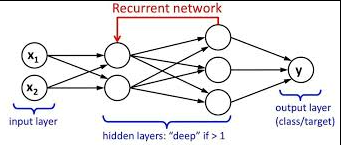

What is Unsupervised Learning? Unsupervised Learning is a machine learning technique in which the users do not need to supervise the model. Instead, it allows the model to work on its own to discover patterns and information that was previously undetected. It mainly deals with the unlabelled data.

#### **LSTM Models**

An LSTM is a version of an RNN network. RNN takes the first input in a sequence and sends its output and the second input to the next step. This iteration continues to the end of the sequence. LSTM models use this structure with three gates. The gates are called the input gate, the forget gate, and the output gate. The first step in LSTM is determining which input must be rejected from the cell state. It can be done using the forget-gate layer function. Now the type of information stored in the cell state is settled. The forget-gate's recurrent activation function triggers the input-gate to define the new value. The selected activation function produces then a new candidate value vector C and it is added to the state. Finally, the output is obtained based on both the cell and a filtered version of it. The designated activation function is used to determine which part of the cell state goes to the output. At that time, the selected recurrent activation function is applied to the method.

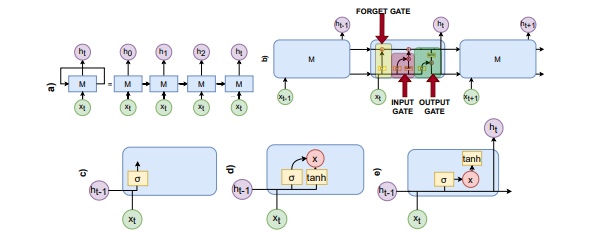

model = pyrun("model = Sequential()","model")

model = sys:1: UserWarning: `Model.state_updates` will be removed in a future version. This property should not be used in TensorFlow 2.0, as `updates` are applied automatically.
sys:1: UserWarning: `layer.updates` will be removed in a future version. This property should not be used in TensorFlow 2.0, as `updates` are applied automatically.
  Python Sequential with properties:

    activity_regularizer: [1×1 py.NoneType]
           compute_dtype: [1×7 py.str]
     distribute_strategy: [1×1 py.tensorflow.python.distribute.distribute_lib._DefaultDistributionStrategy]
                   dtype: [1×7 py.str]
            dtype_policy: [1×1 py.keras.mixed_precision.policy.Policy]
                 dynamic: 0
           inbound_nodes: [1×0 py.list]
              input_spec: [1×1 py.NoneType]
                  layers: [1×0 py.list]
                  losses: [1×0 py.list]
                 metrics: [1×0 

pyrun("model.add((LSTM(hidden_layers, return_sequences=False , activation = 'relu',recurrent_activation='tanh',kernel_initializer='orthogonal',recurrent_initializer='orthogonal',input_shape=(X_test.shape[1],X_test.shape[2]))))",Y_test = Y_test, X_test = X_test)

pyrun("model.add(Dense(hidden_layers*2/3,activation='relu'))")
pyrun("model.add(Dense(1))")
pyrun("model.compile(loss='mae', optimizer='Adam')")
pyrun("history = model.fit(X_train, Y_train, epochs=400, batch_size= 32,validation_data=(X_test, Y_test),callbacks=[EarlyStopping(monitor='val_loss', patience=10)], verbose=1, shuffle=False)", X_train = X_train, Y_train = Y_train, X_test = X_test, Y_test = Y_test)

Epoch 1/400

35/35 [==============================] - 2s 34ms/step - loss: 0.4935 - val_loss: 0.5729
Epoch 2/400

 4/35 [==>...........................] - ETA: 0s - l


pyrun("model.summary()")

Model: "sequential_1"
_________________________________________________________________
 Layer (type)                Output Shape              Param #   
 lstm_1 (LSTM)               (None, 8)                 320       
                                                                 
 dense_2 (Dense)             (None, 5)                 45        
                                                                 
 dense_3 (Dense)             (None, 1)                 6         
                                                                 
Total params: 371
Trainable params: 371
Non-trainable params: 0
_________________________________________________________________


#### **Mean Absolute Error**

Mean Absolute Error is a model evaluation metric used with machine learning models. The mean absolute error of a model with respect to a test set is the mean of the absolute values of the individual prediction errors on over all instances in the test set. Each prediction error is the difference between the true value and the predicted value for the instance.

#### **Root Mean Squared Error**

Root Mean Square Error (RMSE) is the standard deviation of the residuals (prediction errors). Residuals are a measure of how far from the regression line data points are; RMSE is a measure of how spread out these residuals are. In other words, it tells you how concentrated the data is around the line of best fit. Root mean square error is commonly used in climatology, forecasting, and regression analysis to verify experimental results.

% make predictions
train_predict = pyrun("train_predict= model.predict(X_train, verbose = 1)","train_predict",X_train = X_train, model = model);


35/35 [==============================] - 0s 4ms/step


test_predict = pyrun("test_predict = model.predict(X_test,verbose = 1)","test_predict",X_test = X_test, model = model);


9/9 [==============================] - 0s 4ms/step


train_predict_test = double(train_predict.data);
test_predict_test = double(test_predict.data);

test_forecast = test_predict;

%invert predictions
train_predict = pyrun("train_predict = scaler.inverse_transform(train_predict)","train_predict",scaler = scaler);
Y_train = pyrun("Y_train = scaler.inverse_transform(Y_train)", "Y_train");
test_predict = pyrun("test_predict = scaler.inverse_transform(test_predict)","test_predict");

test_predict =   Python ndarray:

    8.1259
    7.6874
    7.5522
   10.7968
   11.5277
   10.2016
   11.5809
   10.4877
   10.6198
    9.2991
   13.3393
   10.4093
   10.6923
    8.1575
   10.8396
   10.0430
    8.4307
    9.8452
    9.0683
    8.9992
    7.6325
    7.1339
    7.0967
    8.6868
    9.6206
    8.0378
    7.9226
    6.3276
    8.3282
    5.3390
    6.8857
    8.2754
    8.9965
   10.0440
   10.1553
    9.1288
    9.2583
   11.7257
   13.0572
   11.8064
   11.4891
    8.4258
   10.5612
    8.9247
   11.8796
   11.5196
   11.0652
   10.6616
    8.9629
    8.8276
    9.8232
   10.7939
   14.5714
   12.3489
   12.2473
   12.1837
   14.2106
    9.2805
    9.9185
    9.9609
    8.3904
    8.9421
   10.0609
   10.0884
   10.3332
   11.4352
   11.2454
   10.6403
    8.7290
    9.9532
    7.9146
    7.7995
    8.9899
   10.7895
   11.9791
   12.9286
   13.9937
   14.5689
   11.4809
   10.7462
   10.0242
  

Y_test = pyrun("Y_test = scaler.inverse_transform(Y_test)","Y_test");

disp(["Train Mean Absolute Error:", num2str(mse(transpose(double(Y_train)),double(train_predict)))])

    "Train Mean Absolute Error:"    "180.0017"



disp(["Train Root Mean Absolute Error:", num2str(rmse(transpose(double(Y_train)),double(train_predict)))])

    "Train Root Mean Absolute Error:"    "7.57566      10.4968      11.2176      11.4762      12.4403      11…"



disp(["Test Mean Absolute Error:", num2str(mse(transpose(double(Y_test)),double(test_predict)))])

    "Test Mean Absolute Error:"    "258.5979"



disp(["Test Mean Root Absolute Error:", num2str(rmse(transpose(double(Y_test)),double(test_predict)))])

    "Test Mean Root Absolute Error:"    "8.88569      9.14039      6.55314      5.68314      6.55314      6.…"



We need to check the train loss and test loss in order to validate our model's performance. If test loss converges to 0 with time it means the model is performing good. But if it gets further from 0 it means something is going wrong with model's performance.

loss = pyrun("loss = history.history['loss']", "loss")

loss =   Python list with values:

    [0.4935462176799774, 0.4324210584163666, 0.3351157307624817, 0.1399637907743454, 0.07184022665023804, 0.07232242077589035, 0.071859210729599, 0.07149159163236618, 0.07122070342302322, 0.07099181413650513, 0.07077573239803314, 0.07054264098405838, 0.07031593471765518, 0.07018895447254181, 0.06997022032737732, 0.06968405097723007, 0.06932537257671356, 0.06899383664131165, 0.06843937188386917, 0.06782816350460052, 0.06718501448631287, 0.06649529188871384, 0.06581342965364456, 0.0650460422039032, 0.06432939320802689, 0.06339135766029358, 0.06260555237531662, 0.06190876290202141, 0.06110139563679695, 0.06066985800862312, 0.06041698902845383, 0.060014981776475906, 0.0604172982275486, 0.060189519077539444, 0.060109321027994156, 0.059368524700403214, 0.059410322457551956, 0.05959320813417435, 0.058925874531269073, 0.0588609017431736, 0.05844471603631973, 0.05832650884985924, 0.058112811297178

val_loss = pyrun("val_loss = history.history['val_loss']","val_loss")

val_loss =   Python list with values:

    [0.5728779435157776, 0.4943193793296814, 0.3331421911716461, 0.08094704896211624, 0.07425204664468765, 0.07362689822912216, 0.07309645414352417, 0.07251641899347305, 0.07210850715637207, 0.07179863750934601, 0.07152020186185837, 0.07117553800344467, 0.07077837735414505, 0.07048875093460083, 0.0701984092593193, 0.06966026872396469, 0.06920523941516876, 0.06857290118932724, 0.06775059551000595, 0.06695795059204102, 0.06605469435453415, 0.0652664452791214, 0.06455214321613312, 0.06387902051210403, 0.06320752948522568, 0.06205868721008301, 0.06065119430422783, 0.05992189049720764, 0.058626946061849594, 0.0584002360701561, 0.05799949914216995, 0.05941508710384369, 0.057246994227170944, 0.059468824416399, 0.05708187073469162, 0.0573623962700367, 0.05890535190701485, 0.05679880455136299, 0.05838131904602051, 0.0570673793554306, 0.056225214153528214, 0.05640294402837753, 0.055632065981626

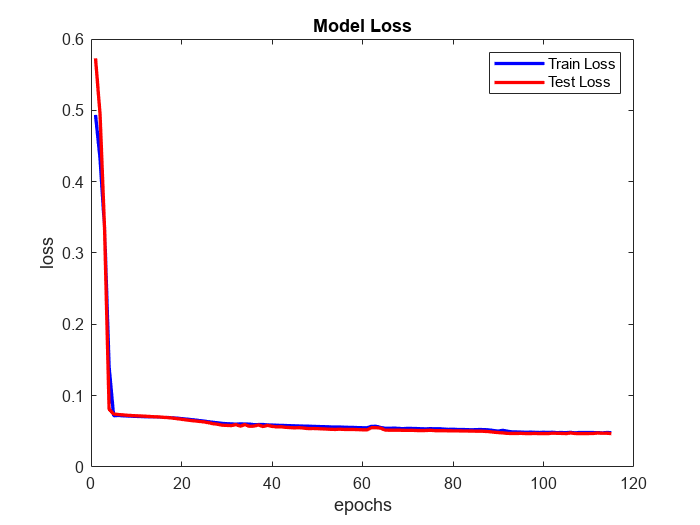

figure
plot(loss,"Linewidth",2,"Color","b")
hold on
plot(val_loss,"Linewidth",2,"Color","r")
legend("Train Loss","Test Loss")
title("Model Loss")
xlabel("epochs")
ylabel("loss")

#### Prediction Plot

prediction = figure

prediction =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


Pred_act = double(Y_test)

Pred_act =     7.8000
    7.5000
   10.8000
   12.2000
   10.8000
   11.6500
   10.8000
   10.5500
    9.2000
   13.0500


Pred_test = transpose(double(test_predict))

Pred_test =     8.1259    7.6874    7.5522   10.7968   11.5277   10.2016   11.5809   10.4877   10.6198    9.2991   13.3393   10.4093   10.6923    8.1575   10.8396   10.0430    8.4307    9.8452    9.0683    8.9992    7.6325    7.1339    7.0967    8.6868    9.6206    8.0378    7.9226    6.3276    8.3282    5.3390    6.8857    8.2754    8.9965   10.0440   10.1553    9.1288    9.2583   11.7257   13.0572   11.8064   11.4891    8.4258   10.5612    8.9247   11.8796   11.5196   11.0652   10.6616    8.9629    8.8276


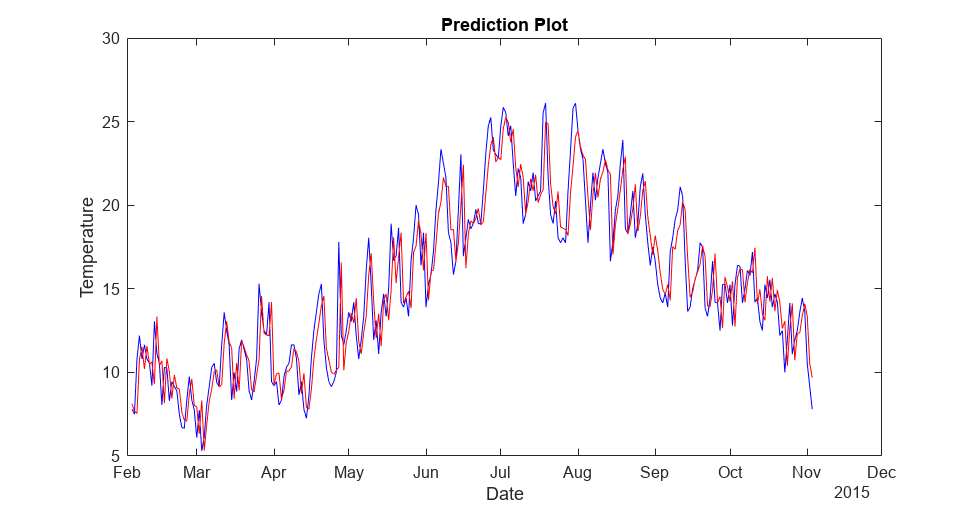

plot((dateList(1,(end-(double(test_size)-double(look_back)-1):end))),Pred_act(end-(double(test_size)-double(look_back)-1):end,1),"Color","b")
hold on
plot((dateList(1,(end-(double(test_size)-double(look_back)-1):end))),Pred_test(1,end-(double(test_size)-double(look_back)-1):end),"Color","r")
ylabel("Temperature")
xlabel("Date")
title("Prediction Plot")
prediction.Position(3:4) = [780 410];

## 7. Forecast

Until now, we predicted earlier temperature values, and our model was able to correct itself with the occurrence of the actual values. It can be called a part of optimizing the model for future forecasting.

We seperated our dataset in the first place. So now we will try to forecast those values without feeding our model with those values. So basically, we are just forecasting future values, but I separated the time series so that we won't have to wait for future values to occur.

Here we create a dataset that includes the data from the last element of the dataset to the time step.

x_input = pyrun("x_input = dataset[-int(look_back):].reshape(1,-1)","x_input",dataset = dataset, look_back = look_back);
temp_input = pyrun("temp_input = list(x_input)","temp_input", x_input = x_input);
temp_input = pyrun("temp_input = temp_input[0].tolist()","temp_input");

pyrun("print(scaler.inverse_transform(x_input))")

[[12.5      13.6      14.450001 13.65     10.55      9.15      7.8     ]]


#### **Forecast**

Here, we are making the forecast possible. We just predict the next value and append this forecasted value to our dataset. Let's say our dataset has 1000 elements in it. We predict the 1001st element. Then we append this 1001st vvalue to the dataset and predict the 1002nd element using the new 1001st element dataset.


lst_output = pyrun("lst_output=[]","lst_output");
n_steps=look_back;
i=uint8(0);
while(i < uint8(look_back)-uint8(1))
if(uint8(length(temp_input))>uint8(look_back))
x_input = pyrun("x_input=np.array(temp_input[1:])","x_input",temp_input = temp_input);
x_input = pyrun("x_input = x_input.reshape(1,-1)","x_input");
pyrun("print(scaler.inverse_transform(x_input))")
x_input = pyrun("x_input = x_input.reshape((int(n_steps),1,1))","x_input",x_input = x_input, n_steps=n_steps);

yhat = pyrun("yhat = model.predict(x_input, verbose = 0)","yhat",model = model);
% yhat = pyrun("yhat = yhat.resahpe(1,1)","yhat")
temp_input = pyrun("temp_input.extend(yhat[0].tolist())","temp_input",yhat = yhat);
temp_input = pyrun("temp_input=temp_input[1:]","temp_input");
lst_output = pyrun("lst_output.extend([yhat[0]])","lst_output",yhat = yhat);
disp("If")
pyrun("print(print('temp input: ',temp_input))",temp_input = temp_input)
pyrun("print('Yhat: ',scaler.inverse_transform(yhat))",yhat = yhat)
pyrun("print('lst_output: ',scaler.inverse_transform(lst_output))", lst_output = lst_output)
i = i+1;
else
x_input = pyrun("x_input = x_input.reshape((int(n_steps),1,1))","x_input",x_input = x_input, n_steps = n_steps);
yhat = pyrun("yhat = model.predict(x_input, verbose = 0)","yhat",  x_input = x_input, model = model);
% yhat = pyrun("yhat = yhat.resahpe(1,1)","yhat")
temp_input = pyrun("temp_input.extend(yhat[0].tolist())","temp_input",yhat = yhat);
lst_output = pyrun("lst_output.extend([yhat[0]])","lst_output",yhat =yhat);
disp("Else")
pyrun("print(print('temp input: ',temp_input))",temp_input = temp_input)
pyrun("print('Yhat: ',scaler.inverse_transform(yhat))",yhat = yhat)
pyrun("print('lst_output: ',scaler.inverse_transform(lst_output))", lst_output = lst_output)
i = i+1;
end
end

Else


temp input:  [0.534426212310791, 0.5704917907714844, 0.5983606576919556, 0.5721310973167419, 0.47049179673194885, 0.424590140581131, 0.38032785058021545, 0.2711236774921417]
None


Yhat:  [[4.4692726]
 [4.703575 ]
 [4.881739 ]
 [4.7142267]
 [4.0676227]
 [3.788387 ]
 [3.5219386]]


lst_output:  [[4.46927258]]


[[13.60000055 14.45000103 13.6499994  10.55000056  9.14999997  7.80000005
   4.46927258]]


If


temp input:  [0.5704917907714844, 0.5983606576919556, 0.5721310973167419, 0.47049179673194885, 0.424590140581131, 0.38032785058021545, 0.2711236774921417, 0.2788057327270508]
None


Yhat:  [[4.703575 ]
 [4.881739 ]
 [4.7142267]
 [4.0676227]
 [3.788387 ]
 [3.5219386]
 [2.8836656]]


lst_output:  [[4.46927258]
 [4.70357528]]


[[14.45000103 13.6499994  10.55000056  9.14999997  7.80000005  4.46927258
   4.70357528]]


If


temp input:  [0.5983606576919556, 0.5721310973167419, 0.47049179673194885, 0.424590140581131, 0.38032785058021545, 0.2711236774921417, 0.2788057327270508, 0.2846471667289734]
None


Yhat:  [[4.881739 ]
 [4.7142267]
 [4.0676227]
 [3.788387 ]
 [3.5219386]
 [2.8836656]
 [2.927429 ]]


lst_output:  [[4.46927258]
 [4.70357528]
 [4.88173902]]


[[13.6499994  10.55000056  9.14999997  7.80000005  4.46927258  4.70357528
   4.88173902]]


If


temp input:  [0.5721310973167419, 0.47049179673194885, 0.424590140581131, 0.38032785058021545, 0.2711236774921417, 0.2788057327270508, 0.2846471667289734, 0.2791549563407898]
None


Yhat:  [[4.7142267]
 [4.0676227]
 [3.788387 ]
 [3.5219386]
 [2.8836656]
 [2.927429 ]
 [2.9608371]]


lst_output:  [[4.46927258]
 [4.70357528]
 [4.88173902]
 [4.7142266 ]]


[[10.55000056  9.14999997  7.80000005  4.46927258  4.70357528  4.88173902
   4.7142266 ]]


If


temp input:  [0.47049179673194885, 0.424590140581131, 0.38032785058021545, 0.2711236774921417, 0.2788057327270508, 0.2846471667289734, 0.2791549563407898, 0.25795483589172363]
None


Yhat:  [[4.0676227]
 [3.788387 ]
 [3.5219386]
 [2.8836656]
 [2.927429 ]
 [2.9608371]
 [2.929423 ]]


lst_output:  [[4.46927258]
 [4.70357528]
 [4.88173902]
 [4.7142266 ]
 [4.06762289]]


[[9.14999997 7.80000005 4.46927258 4.70357528 4.88173902 4.7142266
  4.06762289]]


If


temp input:  [0.424590140581131, 0.38032785058021545, 0.2711236774921417, 0.2788057327270508, 0.2846471667289734, 0.2791549563407898, 0.25795483589172363, 0.24879956245422363]
None


Yhat:  [[3.788387 ]
 [3.5219386]
 [2.8836656]
 [2.927429 ]
 [2.9608371]
 [2.929423 ]
 [2.809119 ]]


lst_output:  [[4.46927258]
 [4.70357528]
 [4.88173902]
 [4.7142266 ]
 [4.06762289]
 [3.78838703]]


Here we just apply the inverse transform to get the effect of minmax scale back to normal values.

lst_output = pyrun("lst_output = scaler.inverse_transform(lst_output)","lst_output");
last_pred = pyrun("last_pred = (test_predict[-1].tolist())","last_pred");
lst_output = pyrun("lst_output = lst_output.tolist()","lst_output");
lst_output = pyrun("lst_output.insert(0,last_pred)","lst_output"); 
pyrun('print(last_pred)')

[9.688143730163574]


pyrun('print(len(lst_output))')

7


lst_output_array = pyrun("lst_output_array = np.array(lst_output)","lst_output_array")

lst_output_array =   Python ndarray:

    9.6881
    4.4693
    4.7036
    4.8817
    4.7142
    4.0676
    3.7884

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


forecast_index = dateList(1,(end-(look_back - 1)):end) + days(look_back -1)

forecast_index = 1×7 datetime array
   2015 Nov 03   2015 Nov 04   2015 Nov 05   2015 Nov 06   2015 Nov 07   2015 Nov 08   2015 Nov 09


#### **Forecast Plot**

df_temp_average = pyrun("df_temp_average = df.temp_average","df_temp_average")

df_temp_average =   Python Series with properties:

                          T: [1×1 py.pandas.core.series.Series]
                      array: [1×1 py.pandas.core.arrays.numpy_.NumpyExtensionArray]
                         at: [1×1 py.pandas.core.indexing._AtIndexer]
                      attrs: [1×1 py.dict]
                       axes: [1×1 py.list]
                      dtype: [1×1 py.numpy.dtypes.Float64DType]
                     dtypes: [1×1 py.numpy.dtypes.Float64DType]
                      empty: 0
                      flags: [1×1 py.pandas.core.flags.Flags]
                    hasnans: 0
                        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
                       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
                      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
    is_monotonic_decreasing: 0
    is_monotonic_increasing: 0
                  is_unique

df_temp_average_values = double(df_temp_average.tolist());

forecast = figure

forecast =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


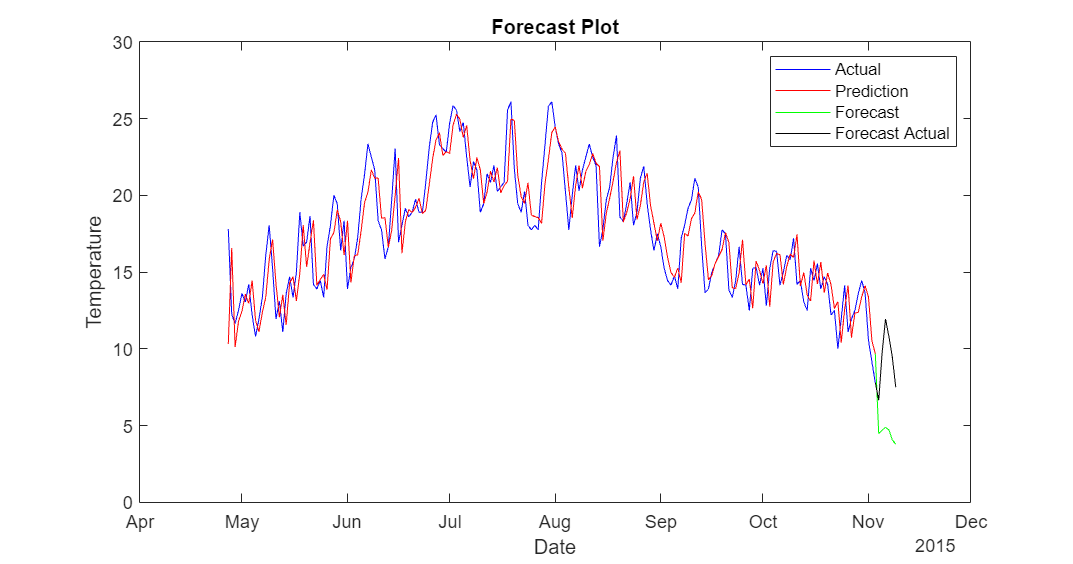

Act = double(Y_test);
Pred_test = transpose(double(test_predict));
Forecast_act = df_temp_average_values(1,end+look_back-(length(dateList_forecast) - length(dateList)+ length(forecast_index)-1):end+look_back-((length(dateList_forecast) - length(dateList))));
plot(dateList(1,end-190:end),Act(end-190:end,1),"Color","b")
hold on
plot(dateList(1,end-190:end),Pred_test(1,end-190:end),"Color","r")
hold on
plot(forecast_index,double(lst_output_array),"Color","g")
hold on
plot(forecast_index,Forecast_act,"Color","k")
ylabel("Temperature")
xlabel("Date")
legend("Actual","Prediction","Forecast","Forecast Actual")
title("Forecast Plot")
forecast.Position(3:4) = [780 410];

#### Magnitude of Forecast

Finding the correct trend is the most important part in forecasting. We can find the magnitude with some easy math operations.

multiplier = 2.1;
lst_output_mult = pyrun("lst_output_mult = np.array(lst_output)","lst_output_mult",lst_output = lst_output) 

lst_output_mult =   Python ndarray:

    9.6881
    4.4693
    4.7036
    4.8817
    4.7142
    4.0676
    3.7884

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


lst_shorten = double(lst_output_mult.data);
for i = 1:(length(lst_output_mult.tolist()) - 2)
    lst_shorten(i+2,1) = lst_shorten(i+2,1) * multiplier;    
end

#### New Forecast Plot

forecast1 = figure

forecast1 =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


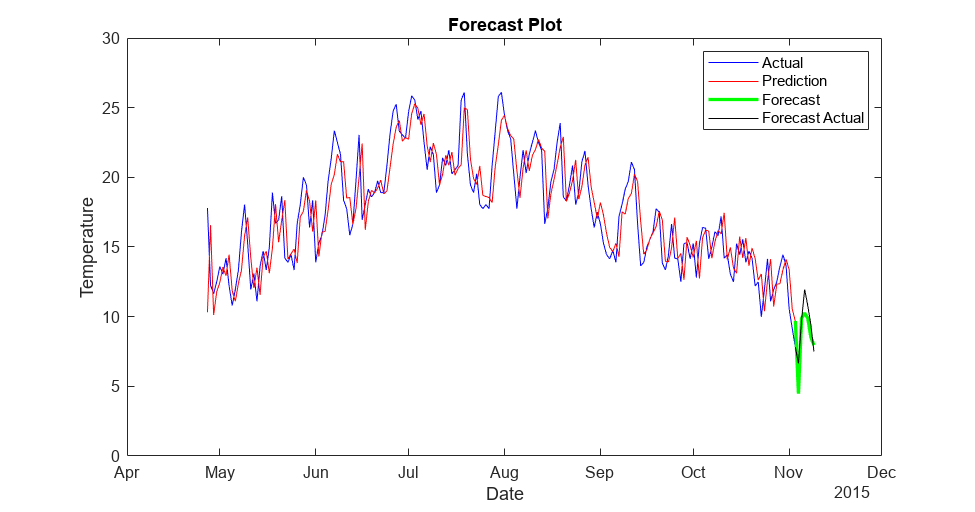

Act = double(Y_test);
Pred_test = transpose(double(test_predict));
Forecast_act = df_temp_average_values(1,end+look_back-(length(dateList_forecast) - length(dateList)+ length(forecast_index)-1):end+look_back-((length(dateList_forecast) - length(dateList))));
plot(dateList(1,end-190:end),Act(end-190:end,1),"Color","b")
hold on
plot(dateList(1,end-190:end),Pred_test(1,end-190:end),"Color","r")
hold on
plot(forecast_index,double(lst_shorten),"Color","g","LineWidth",2)
hold on
plot(forecast_index,Forecast_act,"Color","k")
ylabel("Temperature")
xlabel("Date")
legend("Actual","Prediction","Forecast","Forecast Actual")
title("Forecast Plot")
forecast1.Position(3:4) = [780 410];

It is a work by